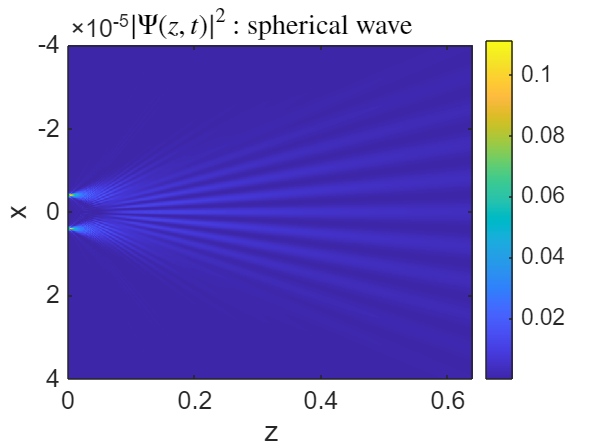

hbar = [1.044e-34,1]; 

N = 2^16;

xmax = 10e-3;        

dx = xmax/N;

n = 0:1:(N-1); p = n;

xn = -xmax/2 + n*dx;


pmax = 2*pi*hbar(1)/dx;

dp = 2*pi*hbar(1)/xmax;

pn = -pmax/2 + p.*dp;


z_sa = 64e-2;                    
z_ad = 64e-2;                       
source_slit = 2e-6;            

detector_size = 80e-6;          
lam_dB = 1.03e-10;             
m_n = 1.675e-27;                
d = 8e-6;                     
diffract_slit = 1e-6;       
slit_separation = 8e-6;     
fill_factor = 50;


m_He = 2*m_n;

Nz = 5000;
zend = z_ad;

dz = zend/Nz;
z = 0:dz:zend;

v = 2*pi*hbar(1)/m_He/lam_dB;       

dt = dz/v;

% dU = exp(-1i*pn.^2.*dt./2./m_n./hbar(1));
U = dU(dt,pn,m_He,hbar(1));



rect1 = @(x) double(abs(x) <= diffract_slit/2); 
dslit = rect1(xn - slit_separation/2) + rect1(xn + slit_separation/2);
% figure;
% plot(xn,dslit,'LineWidth',1.5);
x_grating = (2*pi/d).*xn;

gv = 0.5.*square(x_grating,fill_factor) + 0.5;


slit = dslit;

dt = z_sa/v;

psi0source = rect(xn,source_slit);
psi0spherical = slit.*iftptox(dU(dt,pn,m_He,hbar(1)).*ftxtop(psi0source,dx,hbar(1)),dp,hbar(1));

psi0spherical_p = ftxtop(psi0spherical,dx,hbar(1));
Psi0spherical_p = zeros(length(z),length(psi0spherical_p));
Psi0spherical_x = zeros(length(z),length(psi0spherical_p));
for zi = 1:length(z)
    dt = z(zi)./v;
    Psi0spherical_p(zi,:) = dU(dt,pn,m_He,hbar(1)).*psi0spherical_p;
    Psi0spherical_x(zi,:) = iftptox(Psi0spherical_p(zi,:),dp,hbar(1));
end

Psi0 = gv.*Psi0spherical_x(end,:);
ap = (xn >= -detector_size/2 & xn <= detector_size/2);
x_limited = xn(ap);
figure;
imagesc([0,z_ad],[-detector_size/2, detector_size/2],abs(Psi0spherical_x(:,ap)').^2);
set(gca,'FontSize',15);
xlabel('z');
ylabel('x');
title('$|\Psi(z,t)|^2$ : spherical wave',Interpreter='latex');
colormap parula;
colorbar;

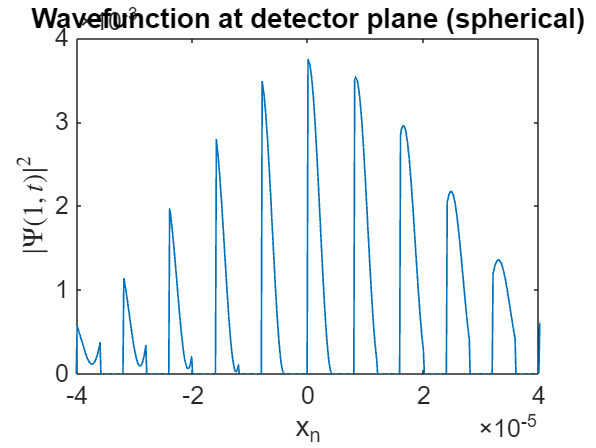


% wavefunction at detector plane
% THIS ISN'T QUITE CORRECT YET. ASK QUESTIONS.
figure;
plot(xn,abs(Psi0).^2,'LineWidth',1);
xlabel('x_n');
ylabel('$|\Psi(1,t)|^2$',Interpreter='latex');
title('Wavefunction at detector plane (spherical)');
xlim([-detector_size/2,detector_size/2]);
set(gca,'FontSize',15);



 
function [U] = dU(dt,p,m,hbar)
    U = exp(-1i.*(p.^2).*dt./2./m./hbar);
end

function y = rect(t,bound)
    y = abs(t) <= bound/2;
    y = double(y);  
end

function [fp] = ftxtop(fx,dx,hbar)
    N  = length(fx);
    fp = dx*(1/2/pi/hbar)^(1/2)*fftshift(fft(ifftshift(fx)));
end

function [fx] = iftptox(fp,dp,hbar)
    N  = length(fp);
    fx = (N)*dp*(1/2/pi/hbar)^(1/2)*ifftshift(ifft(fftshift(fp)));
end